# Models Validation

## 1. Joint 2

Definisco la portante come un segnale sinusoidale a bassa frequenza, con un'ampiezza tale da non sforare i limiti. L'ideale è andare in prossimità dei limiti mantenendo un discreto margine (esempio 70% limiti).

clear all;
clc;
close all;

system=ElasticRoboticSystem();

st=system.getSamplingPeriod;

cs=ControlledSystemScara(system,'Alfa');
cs.setMaxAcceleration(15);
cs.setRestTime(0.1);

omega_portante=0.5;
ampiezza_portante=20;
T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=10; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w1/2/pi,t(end),w0/2/pi, 'logarithmic');
ampliezza_identificazione=60;

Sommo i due segnali

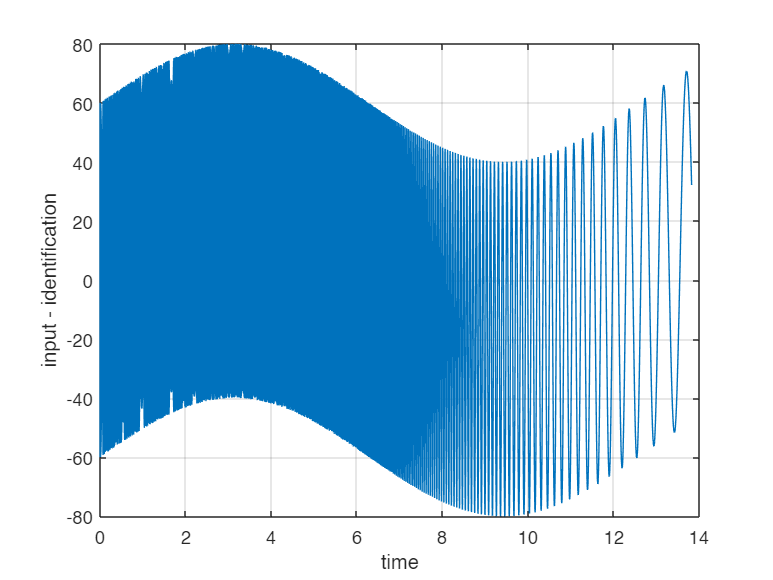

control_action_validation=portante + control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action_validation)
xlabel('time')
ylabel('input - identification')
grid on

### 1.1 Simulation

system.show

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


ans =   ElasticRoboticSystem with no properties.


cs.initialize
tic
ref_j0=0;
x0=zeros(1,4);
k=50/(1/360*2*pi);
x=x0;
s=tf('s');
Ti=10;
PI=k*(1+1/(Ti*s));

controller1=Controller(st,PI,[-600 600]);
torque=zeros(length(control_action_validation),2);
process_output_id2=[];
for idx=1:length(t)
    still_ca = controller1.computeControlAction(ref_j0,x(1));
    [x,t(idx,1)]=cs.openloop([still_ca control_action_validation(idx)]);
    process_output_id2(idx,:) = x;
    torque(idx,:) = [still_ca control_action_validation(idx)];
end
toc

Elapsed time is 15.155650 seconds.


### 1.2 Validation plot

load modello_j2.mat
data=iddata(process_output_id2(:,4),torque(:,2),st)

data =

Time domain data set with 13824 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


omega_filter=10;
filter=s^2/(s+omega_filter)^2

filter =
 
        s^2
  ----------------
  s^2 + 20 s + 100
 
Continuous-time transfer function.



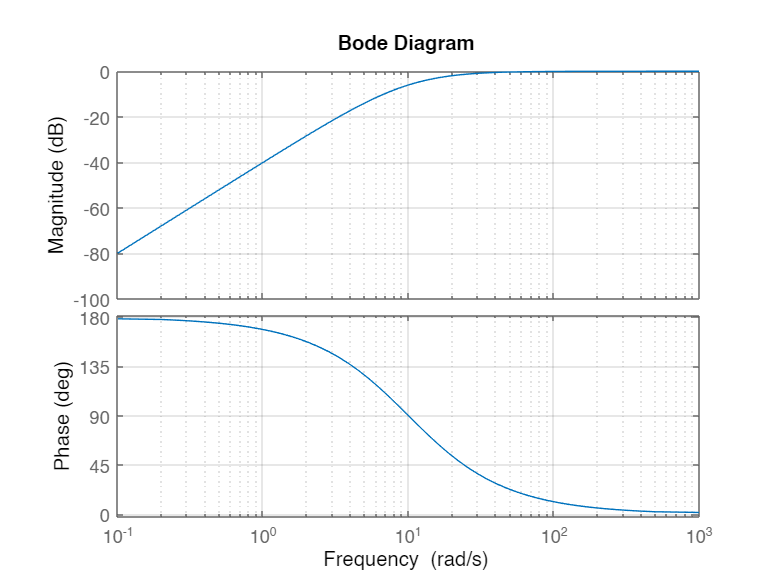

bode(filter)
grid on

filter_d=c2d(filter,st)

filter_d =
 
      z^2 - 2 z + 1
  ---------------------
  z^2 - 1.98 z + 0.9802
 
Sample time: 0.001 seconds
Discrete-time transfer function.



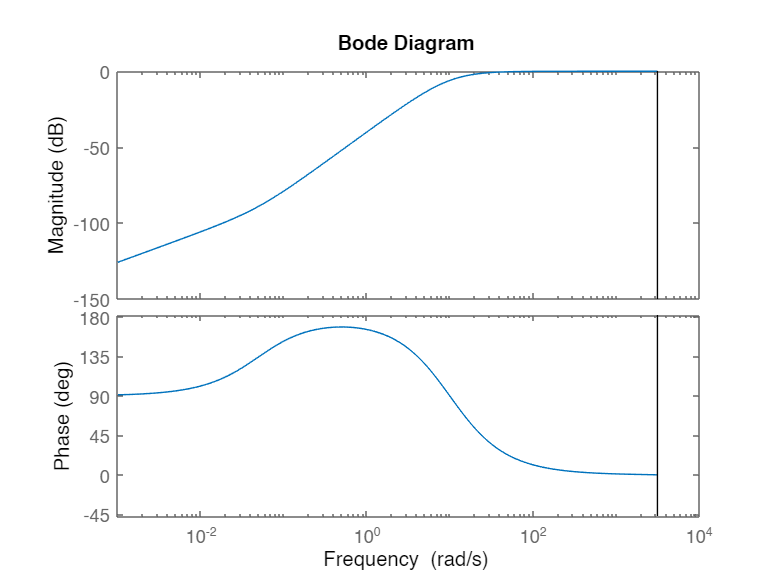

bode(filter_d)

data_filt=idfilt(data,filter)

data_filt =

Time domain data set with 13824 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


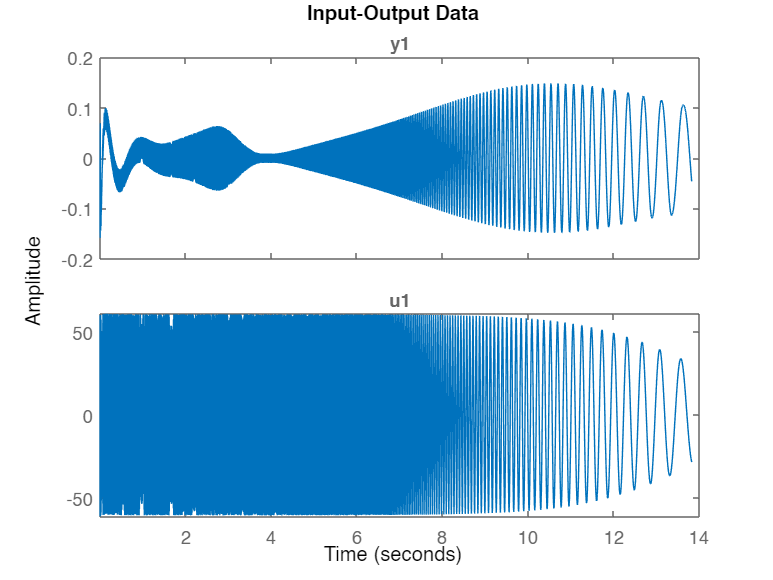

plot(data_filt)

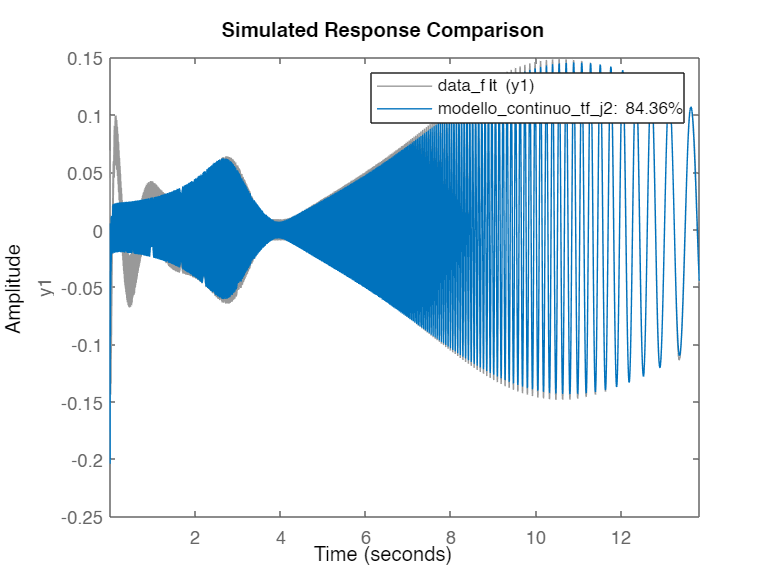


compare(data_filt,modello_continuo_tf_j2)
% Salvataggio della figura
set(gcf,'renderer','painters')

%exportgraphics(gcf,'valid_joint2.emf')

## 2. Join1

Definisco la portante come un segnale sinusoidale a bassa frequenza, con un'ampiezza tale da non sforare i limiti. L'ideale è andare in prossimità dei limiti mantenendo un discreto margine (esempio 70% limiti).

omega_portante=0.5;
ampiezza_portante=20;
T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=10; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w1/2/pi,t(end),w0/2/pi, 'logarithmic');
ampliezza_identificazione=80;

Sommo i due segnali

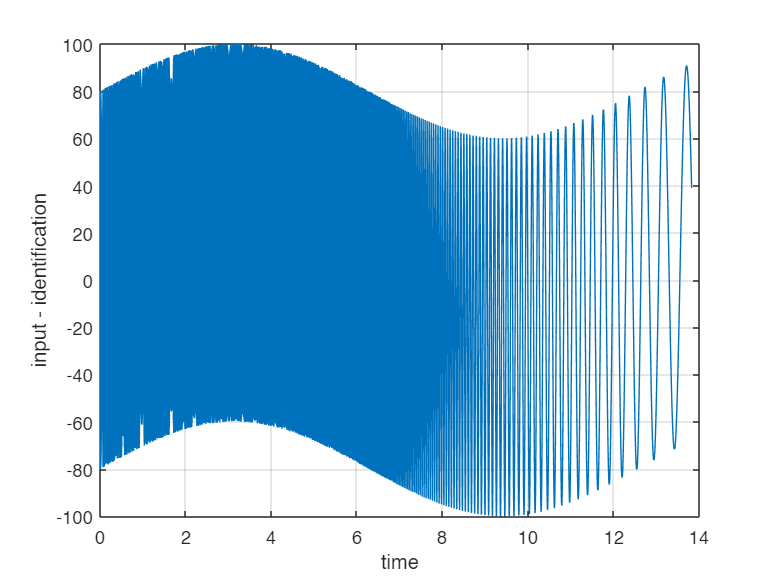

control_action_validation_j1=portante + control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action_validation_j1)
xlabel('time')
ylabel('input - identification')
grid on

### 2.1 Simulation

system.show

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


ans =   ElasticRoboticSystem with no properties.


cs.initialize
tic
ref_j0=0;
x0=zeros(1,4);
x=x0;

load("draftController.mat")

pi_d=c2d(C,st);
controller1=Controller(st,C,1);
controller1.setUMax(600);
torque=zeros(length(control_action_validation_j1),2);
process_output_id1=[];
torque=[];
for idx=1:length(t)
    still_ca = controller1.computeControlAction(ref_j0,x(2));
    [x,t(idx,1)]=cs.openloop([control_action_validation_j1(idx) still_ca]);
    process_output_id1(idx,:) = x;
    torque(idx,:) = [control_action_validation_j1(idx) still_ca];
end
toc

Elapsed time is 14.059357 seconds.


### 2.2 Validation Plot

load("modello_j1.mat")
data=iddata(process_output_id1(:,3),torque(:,1),st)

data =

Time domain data set with 13824 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


omega_filter=10;
filter=s^2/(s+omega_filter)^2

filter =
 
        s^2
  ----------------
  s^2 + 20 s + 100
 
Continuous-time transfer function.



bode(filter)
grid on

filter_d=c2d(filter,st)

filter_d =
 
      z^2 - 2 z + 1
  ---------------------
  z^2 - 1.98 z + 0.9802
 
Sample time: 0.001 seconds
Discrete-time transfer function.



bode(filter_d)

data_filt=idfilt(data,filter)

data_filt =

Time domain data set with 13824 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


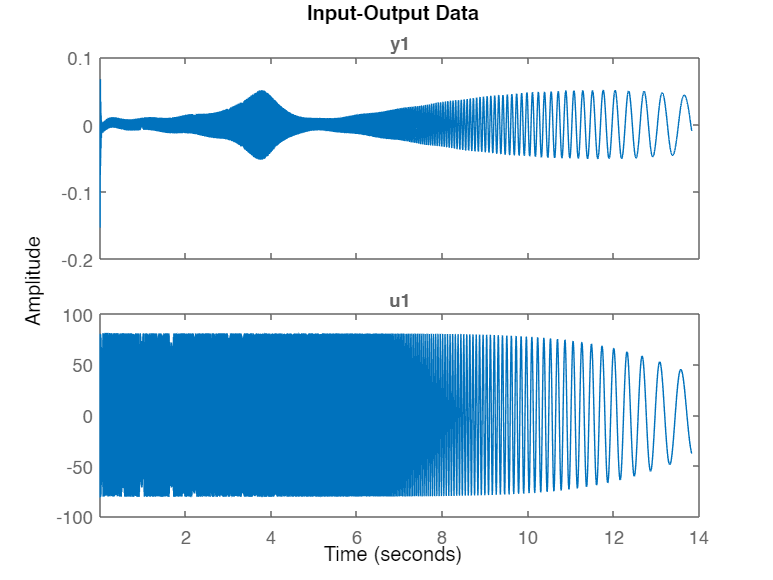

plot(data_filt)

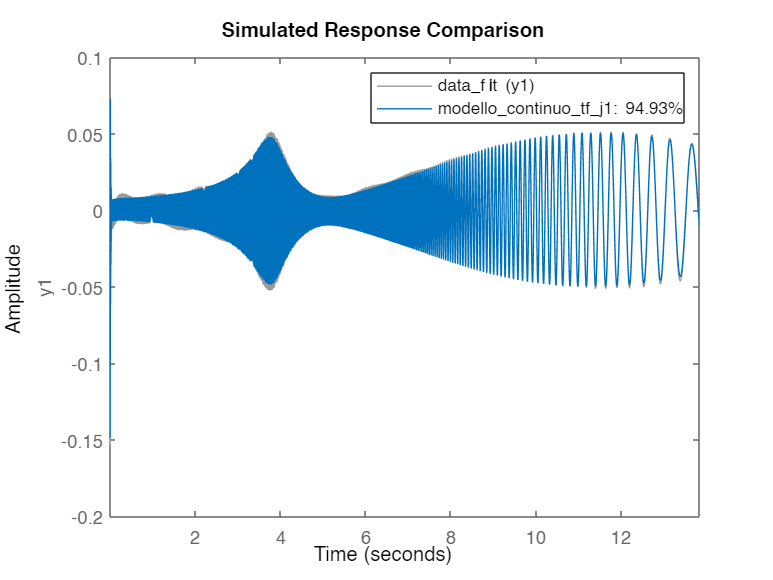

compare(data_filt,modello_continuo_tf_j1)
% Salvataggio della figura
set(gcf,'renderer','painters')
%exportgraphics(gcf,'valid_joint1.emf')